# measured

mfile4='C:\Users\PhotonUser\My Files\Temporary Files\E3.4.txt';
mfileID4=fopen(mfile4);
mtextstuff4=textscan(mfileID4, '%s %s %s %s','Delimiter','\t');
fclose(mfileID4);

mtime4=string(mtextstuff4{1,1});
mtime4=erase(mtime4,'2/11/2022  15:31:');
mvolt4=string(mtextstuff4{1,4});

mtime4=mtime4(1151:2400);
mvolt4=mvolt4(1151:2400);

mtime4=str2double(mtime4);
mvolt4=str2double(mvolt4);

mtime4=mtime4-mtime4(1);
mvolt4=mvolt4-mvolt4(1);

## simulated

ssfile4='C:\Users\PhotonUser\My Files\Temporary Files\Lab 3 q3.csv';
ssdata4=readmatrix(ssfile4);

sstime4=ssdata4(:,1);
ssvolt4=ssdata4(:,2);

sstime4=sstime4(1:2000);
ssvolt4=ssvolt4(1:2000);

## values

p='percent overshoot=54.17%';

## plot

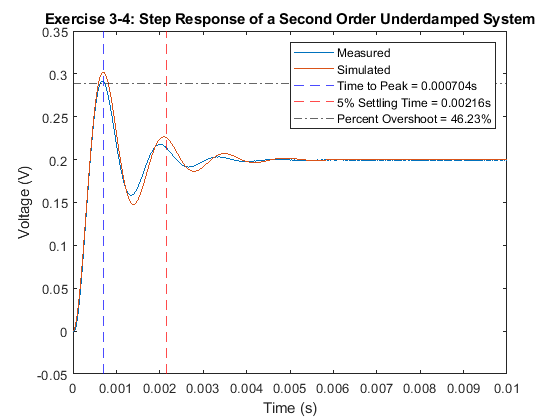

plot(mtime4,mvolt4,'DisplayName','Measured');
hold on
plot(sstime4,ssvolt4,'DisplayName','Simulated');
hold on 
xline(0.000704,'--','color','b','DisplayName','Time to Peak = 0.000704s');
hold on
xline(0.00216,'--','color','r','DisplayName','5% Settling Time = 0.00216s');
hold on
% yline(0.200,'-','DisplayName','Input=0.200V');
% hold on
yline(0.28916,'-.','DisplayName','Percent Overshoot = 46.23%');
hold on

xlabel('Time (s)');
ylabel('Voltage (V)');
title('Exercise 3-4: Step Response of a Second Order Underdamped System');

legend
hold off